# Comparing Antenna Element Calculations with NeoRadium

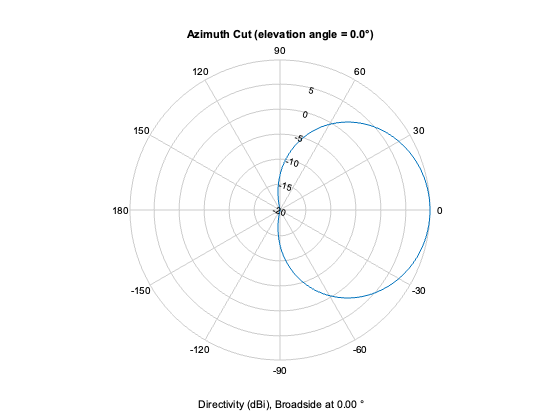

antenna = phased.NRAntennaElement;
fc = 6e9;
pattern(antenna,fc,-180:180,0,'CoordinateSystem','polar','type', 'directivity');

a = pattern(antenna,fc,-180:180,0,'CoordinateSystem','polar','type', 'directivity');
a(176:185)

ans =    9.754679130857767
   9.780241261035258
   9.800122917839985
   9.814324101271950
   9.822844811331152
   9.825685048017533
   9.822844811331152
   9.814324101271950
   9.800122917839985
   9.780241261035258


Note that matlab does not show the clipping to the lower bound clearly.

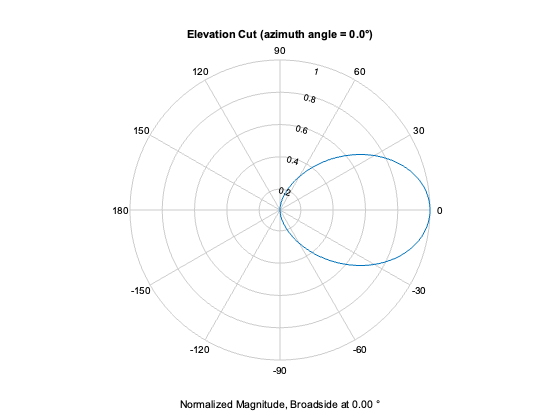

pattern(antenna,fc,0,-90:90,'CoordinateSystem','polar','type', 'efield');

a = pattern(antenna,fc,0,-90:90,'CoordinateSystem','polar','type', 'efield');
a(131:140)

ans =    0.592626496609505
   0.577135922096445
   0.561682799045083
   0.546286059889689
   0.530964015120688
   0.515734323112744
   0.500613962890720
   0.485619209856397
   0.470765614484885
   0.456067983985986


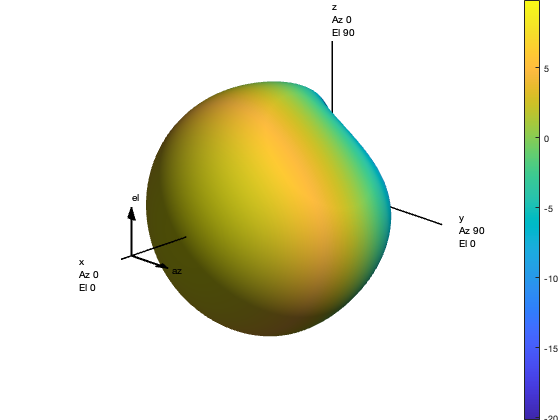


pattern(antenna,fc,'ShowArray',true);

% Saving files 
outPath = fileparts(matlab.desktop.editor.getActiveFilename);

directivity = pattern(antenna,fc,'ShowArray',true);
save(strcat(outPath,'/ElementDirectivity.mat'),'directivity');

powerDb = pattern(antenna,fc,'ShowArray',true, 'type', 'powerdb', 'Normalize', false);
save(strcat(outPath,'/ElementPowerDb.mat'),'powerDb');

field = pattern(antenna,fc,'ShowArray',true, 'type', 'efield', 'Normalize', false);
save(strcat(outPath,'/ElementField.mat'),'field');

directivity(86:95,181)

ans =    9.754679130857767
   9.780241261035258
   9.800122917839985
   9.814324101271950
   9.822844811331152
   9.825685048017533
   9.822844811331152
   9.814324101271950
   9.800122917839985
   9.780241261035258
